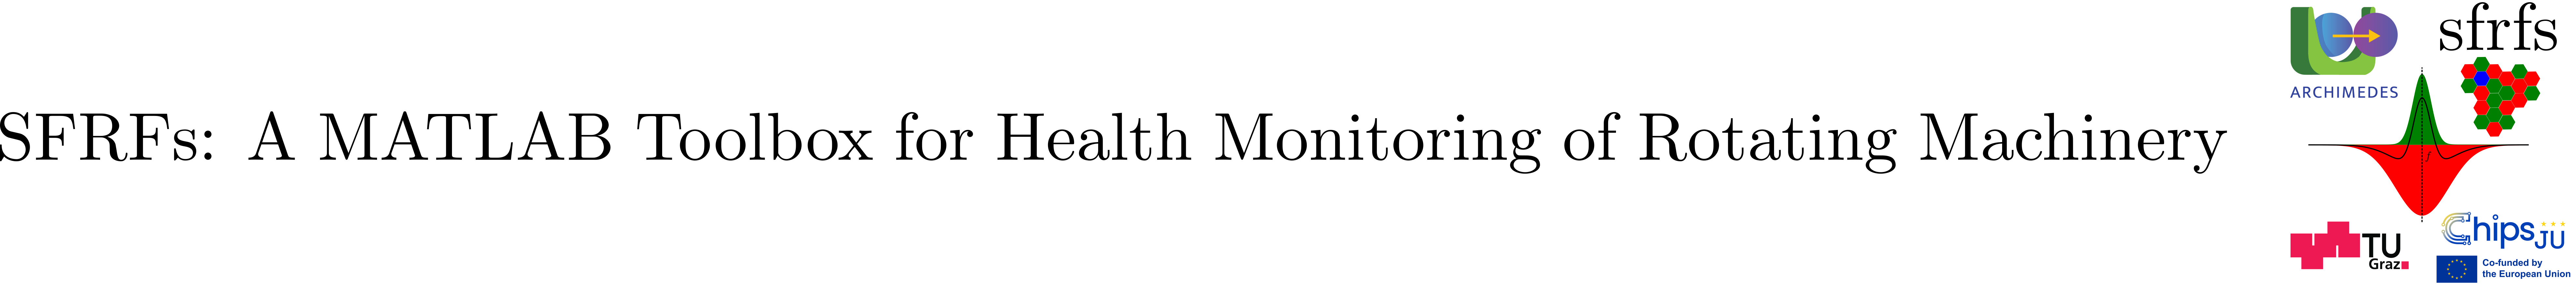

# ContrastPolarityExplorationDatasetBuilder

**(Builds exploration-oriented contrast-polarity datasets across bearing runs)**

## Summary

`ContrastPolarityExplorationDatasetBuilder` is a handle class that constructs exploration-oriented contrast-polarity datasets from ensembles of bearing observations. It integrates harmonic contrast, cross-sensor polarity agreement, temporal polarity events, and traditional condition indicators into a canonical intermediate representation for subsequent analysis.

**Key features:**

- Processes ensembles of bearing runs, preserving individual operating conditions and observation histories.

- Constructs operating-condition-specific lifted harmonic receptive fields for each ensemble member and monitored fault-frequency family.

- Delegates harmonic contrast, agreement filtering, and polarity-event extraction to `ContrastPolarityChannelDatasetBuilder`.

- Integrates traditional time-domain and spectral condition indicators with the contrast-polarity channels.

- Preserves run metadata, monitored fault-family information, and optional bearing failure annotations.

- Produces a canonical table with one row per bearing run and monitored fault-frequency family.

- Supports automatic or user-defined MAT-file naming and storage, including experimental configuration and execution metadata.

- Retains complementary representations for subsequent exploratory analysis without prescribing a diagnostic or prognostic interpretation.

The class provides an ensemble-level dataset construction workflow, while preserving the separation between representation generation and subsequent scientific interpretation.

## Description

`ContrastPolarityExplorationDatasetBuilder` constructs canonical exploration datasets by coordinating the processing of bearing observations across multiple runs and operating conditions. It integrates contrast-polarity representations and traditional condition indicators while preserving the information required for subsequent exploratory analysis.

The builder operates on an ensemble datastore containing bearing observations, spectral representations, and operating-condition metadata. Each ensemble member is processed independently, allowing its harmonic receptive-field parameterization to reflect its own rotational speed and load.

For each ensemble member, dataset construction consists of five stages:

- **Operating-condition-specific receptive-field construction.** The builder retrieves the member's operating conditions, computes the characteristic frequencies of the monitored bearing fault families, and constructs the corresponding `LiftedHarmonicGainFunctions` objects.

- **Contrast-polarity channel construction.** A `ContrastPolarityChannelDatasetBuilder` instance processes the member's spectral observations, computing sensor-local contrasts, cross-sensor agreement, resolved contrasts, and temporal polarity-event channels for each monitored fault family.

- **Traditional condition-indicator computation.** Time-domain and spectral condition indicators are computed from the member's observations and incorporated alongside the contrast-polarity representations.

- **Metadata and annotation integration.** Operating conditions, lifetime information, bearing identifiers, and optional failure annotations are associated with the generated representations.

- **Dataset assembly.** The family-specific rows from all ensemble members are concatenated into a canonical table, accompanied by experimental configuration, processing-time information, and session metadata.

The resulting dataset contains one row per ensemble member and monitored fault-frequency family. Matrix-valued contrast and event channels retain their individual observation-by-harmonic dimensions within table cells, accommodating different observation histories and harmonic counts without global padding.

The `buildFromEnsemble` method executes the complete construction workflow and returns the assembled dataset and its associated metadata. Optional MAT-file storage supports automatically generated filenames or user-defined destinations, preserving the variable naming convention used by the existing experimental workflow.

The class follows an **exploration-driven representation strategy**: complementary observable channels and intermediate computational results are retained without imposing a particular diagnostic hypothesis, degradation model, or prognostic interpretation. Exploration here characterizes the purpose and organization of the generated representations; it does not imply autonomous hypothesis search or adaptive selection of diagnostic features.

**See also:** [`ContrastPolarityChannelDatasetBuilder`](matlab:open('./ContrastPolarityChannelDatasetBuilder.mlx')), [`LiftedHarmonicGainFunctions`](matlab:open('./LiftedHarmonicGainFunctions.mlx')), [`BearingFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx')), [`SFRFsParametersRollingBearings`](matlab:open('./SFRFsParametersRollingBearings.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldResponseFunctions.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')).

### Public properties

`ContrastPolarityExplorationDatasetBuilder` exposes thirteen configuration properties. Their values are established during construction and can be inspected externally, but cannot be reassigned through ordinary property assignment.

All configuration properties have private set access. Their values define the dataset-generation configuration and are reused by `buildFromEnsemble`.

The builder constructs operating-condition-specific lifted harmonic receptive fields during ensemble processing rather than retaining a single shared collection for all members.

### Constructor

The constructor initializes the dataset builder with the experimental configuration used to construct the exploration-oriented representations. Its default parameters reproduce the configuration established for the XJTU-SY bearing experiments.

#### Syntax

`builder = ContrastPolarityExplorationDatasetBuilder()`

`builder = ContrastPolarityExplorationDatasetBuilder( ...`

`    Name = Value, ...)`

#### Parameters

All parameters are optional name-value arguments.

The default SFRF configuration uses order zero, **no sidebands**, one harmonic in the base parameterization, a super-Gaussian center mask with $\alpha=2,\beta=8$, a surround mask with $\alpha=6,\beta=2$, and an inhibition factor of one.

The current implementation requires the fault families in the order BPFO, BPFI, BSF, and FTF.

#### Output

`builder` - `ContrastPolarityExplorationDatasetBuilder` object.

A configured handle object that stores the dataset construction parameters and provides the `buildFromEnsemble` method. Dataset construction is not performed by the constructor.

### buildFromEnsemble

`ContrastPolarityExplorationDatasetBuilder` exposes one public computational method, `buildFromEnsemble`, which constructs a canonical contrast-polarity exploration dataset from an ensemble of bearing observations.

The method builds the exploration dataset by processing the ensemble members independently, using their respective operating conditions to construct lifted harmonic receptive fields and associated contrast-polarity channels.

The method integrates traditional condition indicators and optional failure annotations, assembles the resulting family-specific tables, and produces configuration, timing, and session metadata. The completed dataset may optionally be saved to a MAT-file.

#### Syntax

`result = builder.buildFromEnsemble(ds)`

`result = builder.buildFromEnsemble(ds, ...`

`    saveToFile = true)`

`result = builder.buildFromEnsemble(ds, ...`

`    saveToFile = true, ...`

`    outputFile = "results/exploration_dataset.mat")`

#### Parameters

The input datastore must contain the metadata and signal columns required by the builder's configuration. Spectral representations are expected to be available in the specified columns.

When automatic naming is enabled, the filename follows the convention:

`contrast_polarity_family_channel_dataset_Q95_YYYYMMDD_HHMMSS.mat`

Here, `Q95` corresponds to `quantileLevel = 0.95`. A user-provided filename takes precedence over automatic naming. The `.mat` extension is appended when omitted, and existing files are not overwritten.

#### Output

`result - `scalar structure containing the constructed dataset and associated information.

The canonical table retains operating-condition metadata, traditional condition indicators, sensor-local contrasts, resolved contrasts, agreement-floor histories, and polarity-event channels.

Matrix-valued channels are stored within table cells, preserving the individual observation and harmonic dimensions of each ensemble member.

#### Processing behavior

The method processes the ensemble members sequentially, constructing operating-condition-specific harmonic receptive fields and delegating channel computation to `ContrastPolarityChannelDatasetBuilder`.

When MAT-file storage is enabled, the saved file preserves the experimental naming convention and includes the canonical dataset, configuration information, timing statistics, and session metadata.

Dataset generation and storage do not perform diagnosis, prognosis, or autonomous feature selection. The resulting representations are intended for subsequent exploratory analysis.

## Example

This example constructs an exploration-oriented contrast-polarity dataset from the XJTU-SY[4] bearing ensemble. By default, it processes one complete bearing run from each of the three operating conditions. The complete 15-bearing ensemble can be processed by changing a single configuration option.

The example retains the original experimental parameterization, including all four monitored fault-frequency families, traditional condition indicators, and polarity-event channels.

### Experimental configuration

We begin by defining the execution scope and the dataset-generation options.

%% Experimental configuration

% Process all 15 bearing runs or one run per operating condition.
processFullEnsemble = false;

% Representative bearing runs.
representativeBearings = [ ...
    "Bearing1_1", ...
    "Bearing2_1", ...
    "Bearing3_1"];

% Dataset storage.
saveDataset = true;

% Agreement-filter quantile.
quantileLevel = 0.95;

### Retrieving and selecting the XJTU-SY ensemble

The XJTU-SY bearing dataset [4] contains 15 bearing runs distributed across three operating conditions. The example retrieves the registered ensemble through `EnsembleDatastoreRegistry` and selects one complete bearing run per operating condition by default.

Setting `processFullEnsemble ``= ``true` processes all 15 runs.

% Retrieve and select the XJTU-SY ensemble

% Retrieve the registered ensemble.
dsFull = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");

if processFullEnsemble
    ds = dsFull;
else
    % Identify ensemble members by their filenames.
    memberFiles = string(dsFull.Files);
    [~, memberNames] = fileparts(memberFiles);

    % Select the requested complete bearing runs.
    selected = ismember(memberNames, representativeBearings);

    % Ensure every requested bearing is available.
    assert(all(ismember(representativeBearings, memberNames)), ...
        "One or more representative bearings are missing.");

    % Create a subset without modifying the registered ensemble.
    ds = subset(dsFull, find(selected));
end

% Inspect the selected ensemble.
fprintf("Selected bearing runs: %d of %d\n", ...
    ds.NumMembers, dsFull.NumMembers);

disp(string(ds.Files));

### Constructing the exploration dataset builder

The `ContrastPolarityExplorationDatasetBuilder` constructor initializes the configuration used to generate the exploration dataset. The default parameterization includes the XJTU-SY bearing geometry, spectral and temporal sensor channels, four monitored fault-frequency families, and the corresponding receptive-field and contrast-processing settings.

For this example, the agreement-filter quantile is specified explicitly. All other configuration parameters retain their documented defaults.

% Construct the exploration dataset builder

Selected bearing runs: 3 of 15



% Recover the original XJTU-SY failure annotations.

    "/home/stan/tmp/DX26Diffusion/Datastore/Bearing1_1.mat"
    "/home/stan/tmp/DX26Diffusion/Datastore/Bearing2_1.mat"
    "/home/stan/tmp/DX26Diffusion/Datastore/Bearing3_1.mat"



diagnosisTable = localXJTUSYDiagnosisTable();

% Configure the builder.
builder = ContrastPolarityExplorationDatasetBuilder( ...
    quantileLevel = quantileLevel, ...
    diagnosisTable = diagnosisTable);

disp(builder);

### Build the exploration dataset

The following operation constructs the exploration dataset for the selected bearing histories. This involves evaluating the harmonic receptive fields, building the corresponding contrast-polarity channels, and assembling the resulting family-level observations and condition indicators.

**Computational cost:** The complete execution on three representative XJTU-SY bearing histories required approximately 125 minutes (7,512 seconds), with channel construction accounting for more than 99% of the execution time. Execution time depends on the number and length of the bearing histories, the receptive-field configuration, and the available computational resources.

%% Build the exploration dataset

result = builder.buildFromEnsemble( ...
    ds, ...
    saveToFile = saveDataset);


% Report computational timing and generated dataset.

  ContrastPolarityExplorationDatasetBuilder with properties:

              SnapshotParameters: [1×1 ParametersSnapshot]
               BearingParameters: [1×1 ParametersRollingBearings]
                 SFRFsParameters: [1×1 SFRFsParametersRollingBearings]
                 TemporalColumns: ["HorizontalAcceleration"    "VerticalAcceleration"]
                 SpectralColumns: ["HorizontalAcceleration_FFT"    "VerticalAcceleration_FFT"]
                     FamilyNames: ["BPFO"    "BPFI"    "BSF"    "FTF"]
    ReceptiveFieldResponseBinder: @(mask)@(X,f)ReceptiveFieldResponseFunctions.doMaskedMeanAbs(X,f,mask,epsVal)
                 ContrastMapping: @(Rc,Rs,varargin)ContrastMappings.doDifference(Rc,Rs,ContrastMappings.resolveParam(varargin,"k",k0))
                   QuantileLevel: 0.9500
                        RiseRate: 0.1429
                        FallRate: 0.0204
                  

localSummarizeExplorationTiming(result);

fprintf("Dataset rows: %d\n", height(result.Table));

if result.Saved
    fprintf("Saved dataset: %s\n", result.OutputFile);
end

### Inspect the exploration dataset

The generated table contains one observation per bearing history and fault-frequency family. Each observation combines the family-level contrast-polarity channels, conventional condition indicators, and associated metadata. The following commands inspect the table schema and display representative observations.

% Inspect the exploration dataset

dataset = result.Table;


Exploration dataset construction
Total runtime: 7512.1 s (125.20 min)

Stage                                           Seconds    Percent
------------------------------------------------------------------
Lifted harmonic construction                       2.47      0.03%
Contrast-polarity channel construction          7475.22     99.51%
Condition indicator construction                   6.58      0.09%
Diagnosis annotation                               0.00      0.00%
Other overhead                                    27.80      0.37%
------------------------------------------------------------------
Total                                           7512.07    100.00%

Snapshots processed: 3152
Average runtime per snapshot: 2.383 s



overview = localSummarizeExplorationDataset(dataset);
disp(overview);

Dataset rows: 12


### Visualization

The following examples illustrate complementary views of the exploration dataset: agreement-floor evolution across fault-frequency families, comparison with conventional condition indicators, and harmonic-level resolved contrast with polarity-reversal events.

#### Agreement floors across fault-frequency families

The first example examines the agreement-floor trajectories for the four monitored fault-frequency families (BPFO, BPFI, BSF, and FTF) over the complete lifetime of `Bearing3_1`. The trajectories are displayed on a common scale, preserving their relative magnitudes and allowing their temporal behavior to be compared directly.

% Visualize agreement floors across fault-frequency families
localPlotAgreementFloorsByFamily(dataset, "Bearing3_1");

Saved dataset: contrast_polarity_family_channel_dataset_Q95_20261022_180426.mat


#### Agreement floor and conventional condition indicator

The second example compares the BPFI agreement-floor trajectory with the maximum RMS condition indicator over the lifetime of `Bearing2_1`, whose diagnosed fault corresponds to the inner raceway.

Both sequences are independently normalized to the interval [0, 1] for visualization, allowing their temporal variations to be examined on a common scale. This comparison is exploratory: normalization removes their original amplitude relationship and does not establish equivalence, correlation, or diagnostic performance.

% Compare agreement floor with a conventional condition indicator
localPlotAgreementFloorVsIndicator( ...
    dataset, "Bearing2_1", "BPFI", "MaxRMS");

Exploration dataset: 12 observations, 37 variables
Bearing histories: 3
Polarity channel dimensions: validated (12/12)



#### Resolved contrast and polarity-reversal events

The final example visualizes the resolved contrast for the BPFO fault-frequency family of `Bearing1_1`. The signed contrast field is displayed as a heatmap over successive snapshots and harmonic channels, with detected polarity-reversal events superimposed as markers.

A symmetric, zero-centered color scale distinguishes positive and negative contrast responses, while the overlay makes it possible to examine the location of polarity reversals within the evolving harmonic representation. Color limits are determined from the 97.5th percentile of absolute contrast values to reduce the influence of extreme responses.

This visualization illustrates the retained harmonic-level structure without reducing the contrast field to a single condition indicator.

% Visualize resolved contrast and polarity reversals

      Bearing       Speed    Load    Family    Snapshots    Harmonics
    ____________    _____    ____    ______    _________    _________

    "Bearing1_1"      35      12     "BPFO"       123          118   
    "Bearing1_1"      35      12     "BPFI"       123           74   
    "Bearing1_1"      35      12     "BSF"        123          176   
    "Bearing1_1"      35      12     "FTF"        123          948   
    "Bearing2_1"    37.5      11     "BPFO"       491          110   
    "Bearing2_1"    37.5      11     "BPFI"       491           69   
    "Bearing2_1"    37.5      11     "BSF"        491          165   
    "Bearing2_1"    37.5      11     "FTF"        491          885   
    "Bearing3_1"      40      10     "BPFO"      2538          103   
    "Bearing3_1"      40 

localPlotResolvedContrastWithReversals( ...
    dataset, "Bearing1_1", "BPFO");

## API Documentation

The MATLAB documentation for `ContrastPolarityExplorationDatasetBuilder` provides access to the class description, configuration properties, constructor, and public methods.

The following commands open the documentation directly from MATLAB.

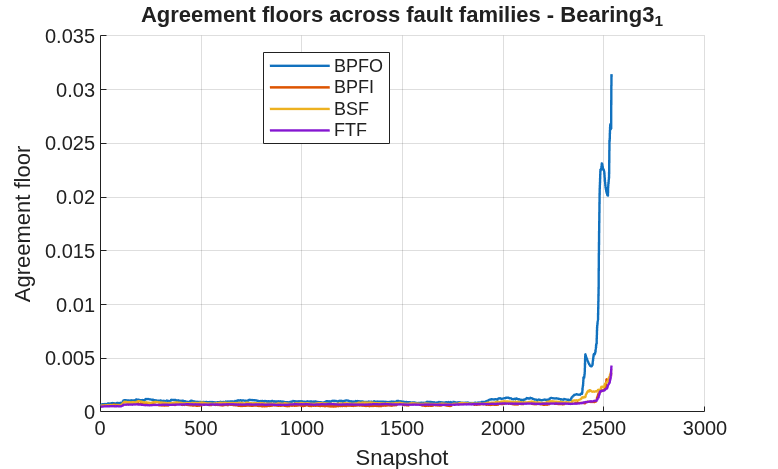

help ContrastPolarityExplorationDatasetBuilder

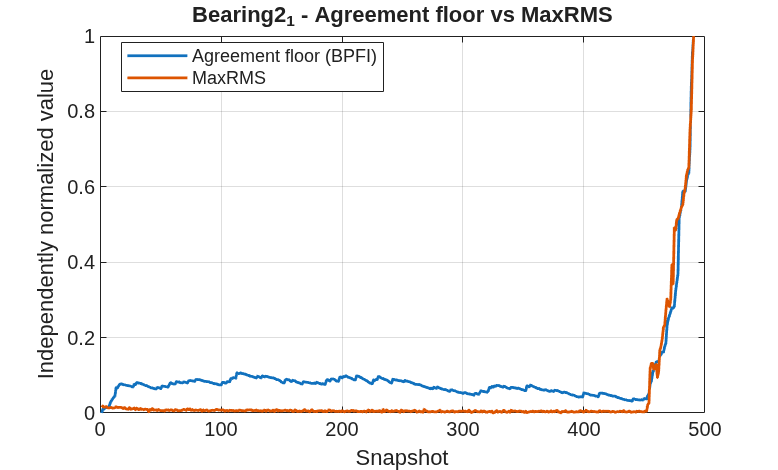

doc ContrastPolarityExplorationDatasetBuilder

## Source Code

The MATLAB implementation of `ContrastPolarityExplorationDatasetBuilder` can be inspected directly using the MATLAB Editor.

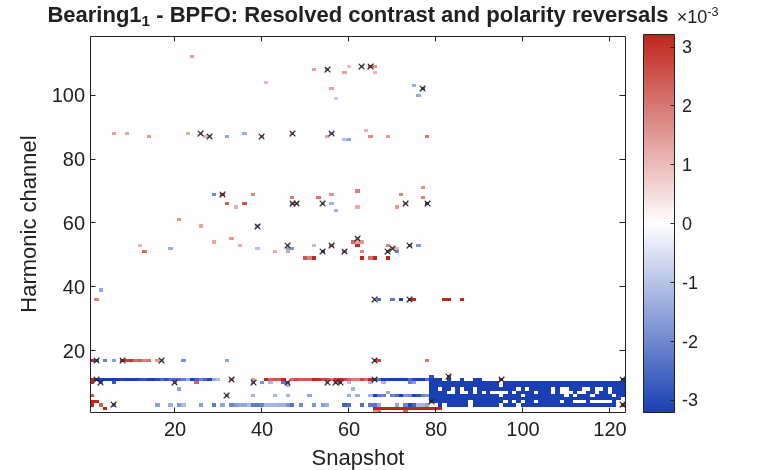

edit ContrastPolarityExplorationDatasetBuilder

## Testing

The dedicated unit tests for `ContrastPolarityExplorationDatasetBuilder` verify its configuration, input validation, and expected behavior. The test suite can be executed independently of the computationally expensive ensemble-processing example.

testResults = runtests("TestContrastPolarityExplorationDatasetBuilder");

 ContrastPolarityExplorationDatasetBuilder Assemble exploratory contrast-polarity data.
 
  An exploratory, intermediate representation: the builder retains
  sensor-local contrasts, agreement-resolved contrast, polarity events,
  and conventional condition indicators. It does NOT infer degradation,
  perform prognosis, select discriminative hypotheses, or learn memories.
 
  One output table row represents one dataset member and one monitored
  bearing-frequency family. Matrix-valued channels remain T_i-by-H_i;
  conventional indicator columns contain T_i-by-1 vectors in cells.
 
  Usage (XJTU-SY configuration from the original script):
    ds = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");
    diagnosisTable = ...; % provide the original XJTU-SY lookup table
    builder = ContrastPolarityExplorationDatasetBuilder( ...
        diagnosisTable = diagnosisTable);
    result = builder.buildFromEnsemble(ds);
    channelRunsQ95 = result.Table;
 
  By de

SFRFsTestUtil.printTestSummary(testResults);

## How to Cite

If you use `ContrastPolarityExplorationDatasetBuilder` in your research, please cite the relevant publications describing the Spectral Fault Receptive Fields methodology and its contrast-polarity extensions:

- Muñoz Gutiérrez, S., & Wotawa, F. (2025). *Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis*. In Proceedings of the 36th International Workshop on Principles of Diagnosis (DX 2025). [https://doi.org/10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9)

- Muñoz Gutiérrez, S., & Wotawa, F. (2026). Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring. In *Proceedings of the 2026 13th International Conference on Dependable Systems and Their Applications (DSA 2026).* IEEE Conference Publishing Services (CPS).

For the XJTU-SY bearing dataset used in the example, please also cite Wang et al. (2020)[4], as listed in the References section.

## Auxiliary functions

### XJTU-SY failure annotations

function tbl = localXJTUSYDiagnosisTable()
%LOCALXJTUSYDIAGNOSISTABLE Original XJTU-SY failure annotations.
%
% Returns the bearing-level failure annotations used in the
% original contrast-polarity experiment.

Label = compose( ...
    "Bearing%d_%d", ...
    repelem(1:3, 5).', ...

Running TestContrastPolarityExplorationDatasetBuilder
.......
Done TestContrastPolarityExplorationDatasetBuilder
__________



    repmat((1:5).', 3, 1));

Test Name                                                    | Result
---------------------------------------------------------------------
TestContrastPolarityExplorationDatasetBuilder/defaultConf... | Passed
TestContrastPolarityExplorationDatasetBuilder/customConfi... | Passed
TestContrastPolarityExplorationDatasetBuilder/rejectsUnsu... | Passed
TestContrastPolarityExplorationDatasetBuilder/explicitFil... | Passed
TestContrastPolarityExplorationDatasetBuilder/rejectsMiss... | Passed
TestContrastPolarityExplorationDatasetBuilder/rejectsInva... | Passed
TestContrastPolarityExplorationDatasetBuilder/rejectsEmpt... | Passed




Failure_O = [ ...
    1 1 1 0 1 ...
    0 1 0 1 1 ...
    1 1 1 0 1].';

Failure_I = [ ...
    0 0 0 0 1 ...
    1 0 0 0 0 ...
    0 1 1 1 0].';

Failure_C = [ ...
    0 0 0 1 0 ...
    0 0 1 0 0 ...
    0 1 0 0 0].';

Failure_B = [ ...
    0 0 0 0 0 ...
    0 0 0 0 0 ...
    0 1 0 0 0].';

tbl = table( ...
    string(Label), ...
    Failure_O, ...
    Failure_I, ...
    Failure_C, ...
    Failure_B, ...
    VariableNames = [ ...
    "Label", ...
    "Failure_O", ...
    "Failure_I", ...
    "Failure_C", ...
    "Failure_B"]);
end

### Visualization of agreement floors across fault families

function localPlotAgreementFloorsByFamily(dataset, bearing)
%LOCALPLOTAGREEMENTFLOORSBYFAMILY Compare family-level agreement histories.

families = ["BPFO", "BPFI", "BSF", "FTF"];

figure(Name = "Agreement floors - " + bearing);
hold on;

for family = families
    row = localSelectExplorationRow(dataset, bearing, family);

    agreement = dataset.AgreementFloor{row};
    snapshots = (1:numel(agreement))';

    plot(snapshots, agreement, ...
        LineWidth = 1.2, ...
        DisplayName = family);
end

hold off;
grid on;

xlabel("Snapshot");
ylabel("Agreement floor");
title("Agreement floors across fault families - " + bearing);
legend(Location = "best");
end

### Visualization of agreement floor versus a conventional indicator

We normalize both sequences independently to the unit interval for visual comparison. This preserves their temporal variation but not their relative amplitudes.

The helper explicitly accepts the selected family and indicator, so its assumptions remain visible at the call site.

function localPlotAgreementFloorVsIndicator(dataset, bearing, family, indicator)
%LOCALPLOTAGREEMENTFLOORVSINDICATOR Compare normalized temporal histories.

row = localSelectExplorationRow(dataset, bearing, family);

assert(ismember(indicator, string(dataset.Properties.VariableNames)), ...
    "Unknown condition indicator: %s", indicator);

agreement = dataset.AgreementFloor{row};
condition = dataset.(indicator){row};

agreement = agreement(:);
condition = condition(:);

assert(numel(agreement) == numel(condition), ...
    "Agreement floor and condition indicator lengths differ.");

agreementNormalized = localNormalizeToUnitInterval(agreement);
conditionNormalized = localNormalizeToUnitInterval(condition);

snapshots = (1:numel(agreement))';

figure(Name = "Agreement vs indicator - " + bearing);

plot(snapshots, agreementNormalized, ...
    LineWidth = 1.4, ...
    DisplayName = "Agreement floor (" + family + ")");
hold on;

plot(snapshots, conditionNormalized, ...
    LineWidth = 1.4, ...
    DisplayName = indicator);

hold off;
grid on;

xlabel("Snapshot");
ylabel("Independently normalized value");
title(bearing + " - Agreement floor vs " + indicator);
legend(Location = "best");
end

### Visualization of resolved contrast with polarity-reversal overlay

This uses the signed heatmap and overlays reversal locations. We choose symmetric color limits based on the 97.5th percentile of the absolute contrast values to reduce the influence of extreme observations.

function localPlotResolvedContrastWithReversals(dataset, bearing, family)
%LOCALPLOTRESOLVEDCONTRASTWITHREVERSALS Visualize signed contrast and events.

row = localSelectExplorationRow(dataset, bearing, family);

contrast = dataset.ResolvedContrast{row};
reversals = dataset.PolarityReversal{row};

assert(isequal(size(contrast), size(reversals)), ...
    "Resolved contrast and reversal dimensions differ.");

figure(Name = "Resolved contrast - " + bearing + " - " + family);

imagesc(contrast.');
axis xy;

colormap(localSignedContrastColormap(256));
colorbar;

finiteValues = abs(contrast(isfinite(contrast)));

if ~isempty(finiteValues)
    colorLimit = prctile(finiteValues, 97.5);

    if colorLimit > 0
        clim([-colorLimit, colorLimit]);
    end
end

hold on;

[snapshotIndex, harmonicIndex] = find(reversals);

plot(snapshotIndex, harmonicIndex, 'x', ...
    Color = [0.15, 0.15, 0.15], ...
    MarkerSize = 4, ...
    LineWidth = 0.6);

hold off;

xlabel("Snapshot");
ylabel("Harmonic channel");
title(bearing + " - " + family + ...
    ": Resolved contrast and polarity reversals");
end

### Visualization utils

These three small utilities keep row selection, normalization, and color mapping consistent.

function row = localSelectExplorationRow(dataset, bearing, family)
%LOCALSELECTEXPLORATIONROW Find a unique bearing-family observation.

selected = string(dataset.Label) == string(bearing) & ...
    string(dataset.MonitoredFaultFamily) == string(family);

assert(nnz(selected) == 1, ...
    "Expected one observation for bearing %s and family %s.", ...
    bearing, family);

row = find(selected);
end


function y = localNormalizeToUnitInterval(x)
%LOCALNORMALIZETOUNITINTERVAL Min-max normalize a finite numeric sequence.

x = double(x);

assert(all(isfinite(x)), ...
    "Cannot normalize a sequence containing nonfinite values.");

lower = min(x);
upper = max(x);

if upper > lower
    y = (x - lower) / (upper - lower);
else
    y = zeros(size(x));
end
end


function cmap = localSignedContrastColormap(n)
%LOCALSIGNEDCONTRASTCOLORMAP Construct a blue-white-red diverging colormap.

if nargin < 1
    n = 256;
end

anchors = [
    0.10 0.25 0.70
    1.00 1.00 1.00
    0.75 0.15 0.12
    ];

positions = [0, 0.5, 1];
samples = linspace(0, 1, n);

cmap = interp1(positions, anchors, samples, "linear");
end

### Summary of computational time

function localSummarizeExplorationTiming(result)
%LOCALSUMMARIZEEXPLORATIONTIMING Summarize computational stage timings.

timing = result.TimingSummary;
total = timing.TotalSeconds;

stages = [
    "Lifted harmonic construction"
    "Contrast-polarity channel construction"
    "Condition indicator construction"
    "Diagnosis annotation"
    ];

seconds = [
    timing.TotalLiftedSeconds
    timing.TotalBuildRowsSeconds
    timing.TotalCIsSeconds
    timing.TotalDiagnosisSeconds
    ];

% Account for execution time not assigned to individual stages.
stages(end+1) = "Other overhead";
seconds(end+1) = total - sum(seconds);

percentages = 100 * seconds / total;

fprintf("\nExploration dataset construction\n");
fprintf("Total runtime: %.1f s (%.2f min)\n\n", ...
    total, total / 60);

fprintf("%-42s %12s %10s\n", ...
    "Stage", "Seconds", "Percent");
fprintf("%s\n", repmat('-', 1, 66));

for k = 1:numel(stages)
    fprintf("%-42s %12.2f %9.2f%%\n", ...
        stages(k), seconds(k), percentages(k));
end

fprintf("%s\n", repmat('-', 1, 66));
fprintf("%-42s %12.2f %9.2f%%\n\n", ...
    "Total", total, 100);

% Report the average processing time per unique snapshot.
[~, idx] = unique(string(result.Table.Label), "stable");
totalSnapshots = sum(result.Table.Lifetime(idx));

fprintf("Snapshots processed: %d\n", totalSnapshots);
fprintf("Average runtime per snapshot: %.3f s\n\n", ...
    total / totalSnapshots);
end

### Summary of dataset structure

function overview = localSummarizeExplorationDataset(dataset)
%LOCALSUMMARIZEEXPLORATIONDATASET Summarize and validate channel dimensions.

n = height(dataset);

required = [
    "Label"
    "Speed"
    "Load"
    "Lifetime"
    "MonitoredFaultFamily"
    "HarmonicCount"
    "HorizontalAcceleration_FFT_C"
    "VerticalAcceleration_FFT_C"
    "AgreementFloor"
    "ResolvedContrast"
    "PolarityReversal"
    ];

assert(all(ismember(required, string(dataset.Properties.VariableNames))), ...
    "Exploration dataset is missing required variables.");

snapshots = zeros(n, 1);
harmonics = zeros(n, 1);

for k = 1:n
    h = dataset.HorizontalAcceleration_FFT_C{k};
    v = dataset.VerticalAcceleration_FFT_C{k};
    a = dataset.AgreementFloor{k};
    c = dataset.ResolvedContrast{k};
    p = dataset.PolarityReversal{k};

    [snapshots(k), harmonics(k)] = size(c);

    assert(isnumeric(h) && isequal(size(h), size(c)), ...
        "Invalid horizontal channel dimensions at row %d.", k);

    assert(isnumeric(v) && isequal(size(v), size(c)), ...
        "Invalid vertical channel dimensions at row %d.", k);

    assert(isnumeric(a) && isequal(size(a), [snapshots(k), 1]), ...
        "Invalid agreement floor dimensions at row %d.", k);

    assert(islogical(p) && isequal(size(p), size(c)), ...
        "Invalid polarity reversal dimensions at row %d.", k);

    assert(dataset.Lifetime(k) == snapshots(k), ...
        "Snapshot count mismatch at row %d.", k);

    assert(dataset.HarmonicCount(k) == harmonics(k), ...
        "Harmonic count mismatch at row %d.", k);
end

overview = table( ...
    string(dataset.Label), ...
    dataset.Speed, ...
    dataset.Load, ...
    string(dataset.MonitoredFaultFamily), ...
    snapshots, ...
    harmonics, ...
    VariableNames = [ ...
    "Bearing", "Speed", "Load", ...
    "Family", "Snapshots", "Harmonics"]);

fprintf("Exploration dataset: %d observations, %d variables\n", ...
    height(dataset), width(dataset));

fprintf("Bearing histories: %d\n", ...
    numel(unique(overview.Bearing)));

fprintf("Polarity channel dimensions: validated (%d/%d)\n\n", ...
    n, n);
end

## References

- [1] Muñoz Gutiérrez, S., & Wotawa, F. (2025). *Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis*. In *Proceedings of the 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025)*, OASIcs, Vol. 136, pp. 9:1–9:20. Schloss Dagstuhl – Leibniz-Zentrum für Informatik. [https://doi.org/10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9)

- [2] Muñoz Gutiérrez, S., & Wotawa, F. (2025). *A Practical Guide to Spectral Fault Receptive Fields: Parameterization and Usage in the SFRFs MATLAB Toolbox*. Technical Report TR-SFRFs-v1.0.1. Zenodo.

- [3] Muñoz Gutiérrez, S., & Wotawa, F. (2026). Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring. In *Proceedings of the 2026 13th International Conference on Dependable Systems and Their Applications (DSA 2026).* IEEE Conference Publishing Services (CPS).

- [4] Wang, B., Lei, Y., Li, N., & Li, N. (2020). *A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings*. IEEE Transactions on Reliability, 69(1), 401–412. [https://doi.org/10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682)